# **[2024-1 확률 시스템 해석(Probability Systems Analysis)]**

- 강의자 : 

- 요구사항 a : MATLAB 버젼을 2023b 이상

- 요구사항 b : `Statistics and Machine Learning Toolbox`를 사용합니다.

clc; clear all; close all;

### A. 이산 확률 시스템의 예제 : Dice roll

S = 6;
N = 1000;       %number of trials
T = 100;        %number of rolls per trial
out = randi([1 S],[T, N]);
sumout=sum(out);
fprintf('Mean(Sum(out))=%.1f.\n',mean(sumout))

Mean(Sum(out))=350.2.


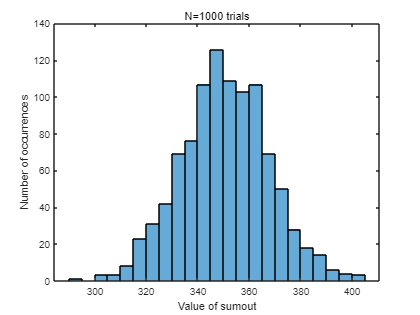


histogram(sumout)
xlabel('Value of sumout');
ylabel('Number of occurrences')
titlestr=sprintf('N=%d trials',N);
title(titlestr)

###  B. 확률 분포

#### 이산 분포

- `binopdf`

- `binocdf`

- `binornd`

#### 푸아송 분포

- poisspdf

- poisscdf

- poissrnd

lambda = 2;

i = 0;
U = rand;
cdf = exp(-lambda);
while(U >= cdf)
    i = i + 1;
    cdf = cdf + exp(-lambda) * lambda;
    i/gamma(i + 1);
end
X = i;

#### 기하 분포

- geopdf

- geocdf

- geornd

#### 정규 분포

- normpdf

- normcdf

- normlike

load examgrades
x = grades(:,1);
pd = fitdist(x,'Normal')

pd =   NormalDistribution

  정규 분포
       mu = 75.0083   [73.4321, 76.5846]
    sigma =  8.7202   [7.7391, 9.98843]


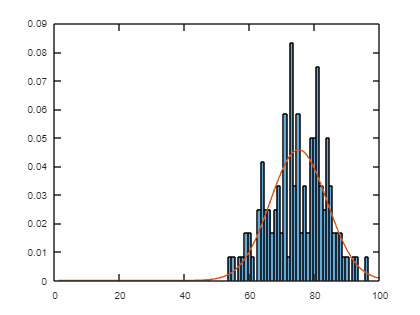

x_pdf = [1:0.1:100];
y = pdf(pd,x_pdf);
 
figure
histogram(x,'Normalization','pdf')
line(x_pdf,y)

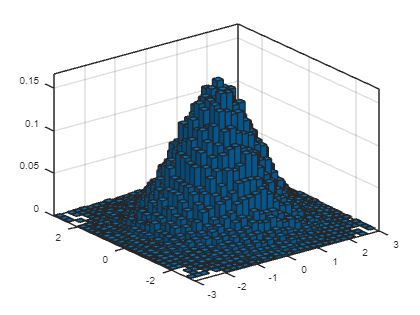

clear all

%// Data (example):
X = randn(1,1e5); % random variables.
Y = randn(1,1e5);

x_axis = -3:.2:3; % Define edges of bins for x axis. Column vector
y_axis = -3:.2:3; % Same for y axis

%// Compute and plot pdf
figure
histogram2(X, Y, x_axis, y_axis, 'Normalization', 'pdf')

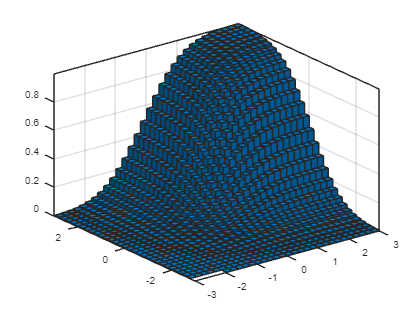


%// Compute and plot cdf
figure
histogram2(X, Y, x_axis, y_axis, 'Normalization', 'cdf')

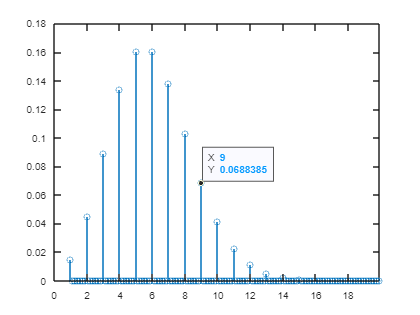

x = 1:0.1:20;
lambda = 6;
y = poisspdf(x,lambda);
stem(x,y)

### Correlation

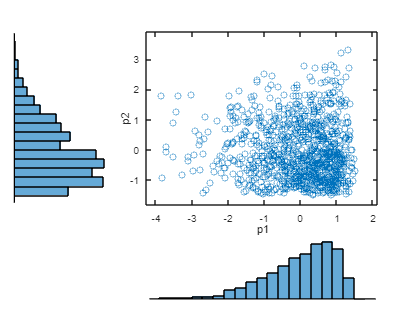

rng default  % For reproducibility
p1 = pearsrnd(0,1,-1,4,1000,1);
p2 = pearsrnd(0,1,0.75,3,1000,1);

figure
scatterhist(p1,p2)

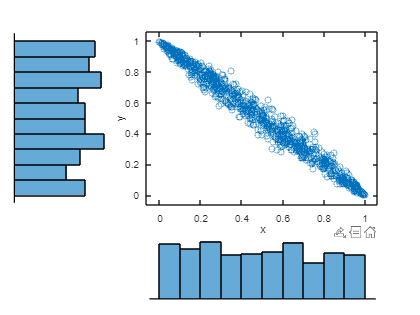

u = copularnd('Gaussian',-0.99,1000);
figure
scatterhist(u(:,1),u(:,2))

### Linear MSE estimation

### Central limit theorem